# Kersbergen et al 2022

% Figure 2
defaultDir = 'F:\Calvin\tmem16a\IC widefield tecta spont'

defaultDir = 'F:\Calvin\tmem16a\IC widefield tecta spont'

cd(defaultDir);
addpath('196_3 flfl','203_1 tecta flfl','203_2 tecta flfl','203_3 flfl','208_1 tecta flfl','208_2 flfl','159_7 tecta wt','165_2 tecta wt','198_5 tecta wt','214_1 tecta flfl','227_1 tecta wt','227_2 tecta wt','227_3 tecta wt','227_4 tecta wt','228_3 tecta flfl','235_2 tecta flfl','235_3 flfl','235_4 tecta flfl','242_1 tecta flfl','242_2 flfl','242_4 flfl','246_1 tecta wt','246_2 tecta wt','280_1 tecta flfl','295_1 flfl','326_1 flfl','326_2 tecta flfl','326_3 flfl')

% cKO 
tectaTM1 = load('dFoFvars203_1.mat');  
tectaTM2 = load('dFoFvars203_2.mat'); % dim retinal waves
tectaTM3 = load('dFoFvars208_1.mat'); 
tectaTM4 = load('dFoFvars214_1.mat'); 
tectaTM5 = load('dFoFvars228_3.mat'); % cloudy window, not as consistent
tectaTM6 = load('dFoFvars235_2.mat');
tectaTM8 = load('dFoFvars242_1.mat');
tectaTM9 = load('dFoFvars280_1.mat');
tectaTM10 = load('dFoFvars326_2.mat');

% Control
tmem1 = load('dFoFvars196_3.mat');
tmem2 = load('dFoFvars203_3.mat');
tmem3 = load('dFoFvars208_2.mat');
tmem4 = load('dFoFvars235_3.mat');
tmem5 = load('dFoFvars242_2.mat');
tmem6 = load('dFoFvars295_1.mat');
tmem7 = load('dFoFvars326_1.mat');
tmem8 = load('dFoFvars326_3.mat');

% large amp events tend to "sweep" from high to low freq in cKO
tmemAmp = [tmem1.stats.meanAll,tmem2.stats.meanAll,tmem3.stats.meanAll,tmem4.stats.meanAll,tmem5.stats.meanAll,tmem6.stats.meanAll,tmem8.stats.meanAll,tmem7.stats.meanAll];
tectaTMAmp = [tectaTM1.stats.meanAll,tectaTM2.stats.meanAll,tectaTM3.stats.meanAll,tectaTM4.stats.meanAll,tectaTM5.stats.meanAll,tectaTM6.stats.meanAll,tectaTM8.stats.meanAll,tectaTM9.stats.meanAll,tectaTM10.stats.meanAll];%,tectatectaTM7.stats.meanAll];
tmemAmp = tmemAmp*100;
tectaTMAmp = tectaTMAmp*100;
tmemFreq = [tmem1.stats.Var8,tmem2.stats.Var8,tmem3.stats.Var8,tmem4.stats.Var8,tmem5.stats.Var8,tmem6.stats.Var8,tmem7.stats.Var8,tmem8.stats.Var8];
tectaTMFreq = [tectaTM1.stats.Var8,tectaTM2.stats.Var8,tectaTM3.stats.Var8,tectaTM4.stats.Var8,tectaTM5.stats.Var8,tectaTM6.stats.Var8,tectaTM8.stats.Var8,tectaTM9.stats.Var8,tectaTM10.stats.Var8];%tectacx7.stats.Var8];
tmemWidth = [tmem1.stats.width,tmem2.stats.width,tmem3.stats.width,tmem4.stats.width,tmem5.stats.width,tmem6.stats.width,tmem7.stats.width,tmem8.stats.width];
tectaTMWidth = [tectaTM1.stats.width,tectaTM2.stats.width,tectaTM3.stats.width,tectaTM4.stats.width,tectaTM6.stats.width,tectaTM8.stats.width,tectaTM9.stats.width,tectaTM10.stats.width];
tmemWidth = tmemWidth./10;
tectaTMWidth = tectaTMWidth./10;
tmemDom = [tmem1.stats.Var12,tmem2.stats.Var12,tmem3.stats.Var12,tmem4.stats.Var12,tmem5.stats.Var12,tmem6.stats.Var12,tmem7.stats.Var12,tmem8.stats.Var12];
tectaTMDom = [tectaTM1.stats.Var12,tectaTM3.stats.Var12,tectaTM4.stats.Var12,tectaTM6.stats.Var12,tectaTM8.stats.Var12,tectaTM9.stats.Var12,tectaTM10.stats.Var12];
tmemCor = [tmem1.stats.LRcorr,tmem2.stats.LRcorr,tmem3.stats.LRcorr,tmem4.stats.LRcorr,tmem5.stats.LRcorr,tmem6.stats.LRcorr,tmem7.stats.LRcorr,tmem8.stats.LRcorr];
tectaTMCor = [tectaTM1.stats.LRcorr,tectaTM2.stats.LRcorr,tectaTM3.stats.LRcorr,tectaTM4.stats.LRcorr,tectaTM5.stats.LRcorr,tectaTM6.stats.LRcorr,tectaTM8.stats.LRcorr,tectaTM9.stats.LRcorr,tectaTM10.stats.LRcorr];
tmemCoVar = [tmem1.stats.coVar,tmem2.stats.coVar,tmem3.stats.coVar,tmem4.stats.coVar,tmem5.stats.coVar,tmem6.stats.coVar,tmem7.stats.coVar,tmem8.stats.coVar];
tectaTMCoVar = [tectaTM1.stats.coVar,tectaTM2.stats.coVar,tectaTM3.stats.coVar,tectaTM4.stats.coVar,tectaTM5.stats.coVar,tectaTM6.stats.coVar,tectaTM8.stats.coVar,tectaTM9.stats.coVar,tectaTM10.stats.coVar];
% two comparison only - P7
conditions2 = {'Control','cKO'};
dim = [1 2];

% frequency
ylbl1 = 'Events per minute';
[fig1 h p1] = compare2(tmemFreq,tectaTMFreq,conditions2,ylbl1,dim);
ylim([0 20])
p1

p1 = 9.4726e-07

[h p1 CI stats1] = ttest2(tmemFreq,tectaTMFreq,'vartype','unequal')

h = 1

p1 = 1.0033e-05

CI =     3.9895    6.9079


stats1 = struct with fields:
    tstat: 8.3611
       df: 9.6487
       sd: [0.5685 1.8597]



% mean amp
ylbl1 = 'Mean amplitude (%dF/F)';
[fig2 h p2] = compare2(tmemAmp,tectaTMAmp,conditions2,ylbl1,dim)

fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = 0

p2 = 0.3698

p2

p2 = 0.3698

ylim([0 20])

% mean width
ylbl1 = 'Event width (s)';
[fig3 h p3] = compare2(tmemWidth,tectaTMWidth,conditions2,ylbl1,dim)

not normal


fig3 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   0


p3 = 0.5737

ylim([0 3])
p3

p3 = 0.5737

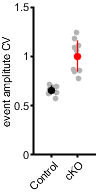


% correlation
ylbl1 = 'L-R IC correlation';
[fig4 h p4] = compare2(tmemCor,tectaTMCor,conditions2,ylbl1,dim);
ylim([0 1])

%coVar
ylbl1 = 'event amplitute CV';
compare2(tmemCoVar,tectaTMCoVar,conditions2,ylbl1,dim);
ylim([0 1.5])

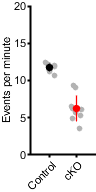

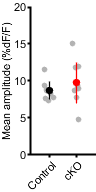

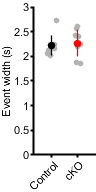

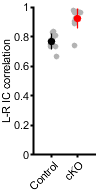


subP = handleTheSubplot({fig1,fig2,fig3,fig4},[1 4]);

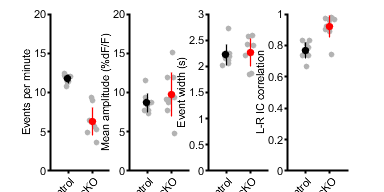

figQuality(subP,gca,[4 2])


[CorrP CorrA h] = fdr_BH([p1,p2,p3,p4],0.05)

CorrP =     0.0000    0.4931    0.5737    0.0005


CorrA =     0.0125    0.0375    0.0500    0.0250


h = 4×1 logical array
   1
   0
   0
   1


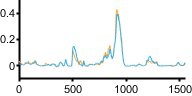

% Peak analysis
% peak analysis - P7 only, by IC

tectaTM1 = load('ICinfo16_dFoF203_1.mat'); 
tectaTM2 = load('ICinfo16_dFoF208_1.mat'); 
tectaTM3 = load('ICinfo16_dFoF214_1.mat'); 
tectaTM4 = load('ICinfo16_dFoF235_2.mat'); 
tectaTM6 = load('ICinfo16_dFoF242_1.mat'); 
tectaTM7 = load('ICinfo16_dFoF280_1.mat'); 
tectaTM8 = load('ICinfo16_dFoF326_2.mat'); 
tectaTM9 = load('ICinfo16_dFoF203_2.mat'); 
tectaTM10 = load('ICinfo16_dFoF228_3.mat'); 

tmem1 = load('ICinfo16_dFoF196_3.mat');
tmem2 = load('ICinfo16_dFoF203_3.mat');
tmem3 = load('ICinfo16_dFoF208_2.mat');
tmem4 = load('ICinfo16_dFoF235_3.mat');
tmem5 = load('ICinfo16_dFoF242_4.mat');
tmem6 = load('ICinfo16_dFoF295_1.mat');
tmem7 = load('ICinfo16_dFoF326_1.mat');
tmem8 = load('ICinfo16_dFoF326_3.mat');

% plot dFoF signal - raw
    lt_org = [255, 166 , 38]/255;
    dk_org = [255, 120, 0]/255;
    lt_blue = [50, 175, 242]/255;
    dk_blue = [0, 13, 242]/255;
figure
   time = [1:1:size(tectaTM1.ICsignal,1)]';
    LIC = smooth(tectaTM1.ICsignal(:,1));
    RIC = smooth(tectaTM1.ICsignal(:,2));

    LIC = msbackadj(time,LIC,'WindowSize',500,'StepSize',500);
    RIC = msbackadj(time,RIC,'WindowSize',500,'StepSize',500);
  

plot(LIC(4050:5600),'Color',lt_org,'LineWidth',1)
hold on
plot(RIC(4050:5600),'Color',lt_blue,'LineWidth',1)
ylim([-0.1 0.5])
figQuality(gcf,gca,[2 1])

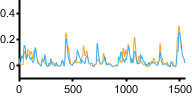


figure
   time = [1:1:size(tmem1.ICsignal,1)]';
    LIC = smooth(tmem1.ICsignal(:,1));
    RIC = smooth(tmem1.ICsignal(:,2));

    LIC = msbackadj(time,LIC,'WindowSize',500,'StepSize',500);
    RIC = msbackadj(time,RIC,'WindowSize',500,'StepSize',500);
  

plot(LIC(975:2525),'Color',lt_org,'LineWidth',1)
hold on
plot(RIC(975:2525),'Color',lt_blue,'LineWidth',1)
ylim([-0.1 0.5])
figQuality(gcf,gca,[2 1])

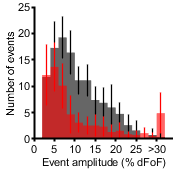

% activity distribution, TAB style

binLim = [0 0.02:.02:.3 100];
binY = [0 .02:.02:.3];
 
lPeakswt1 = (tmem1.pkData((tmem1.pkData(:,7)==1),2));
rPeakswt1 = (tmem1.pkData((tmem1.pkData(:,7)==2),4));
Rcountswt1= histcounts(rPeakswt1,binLim);
Lcountswt1= histcounts(lPeakswt1,binLim);
totalcountswt1= histcounts([rPeakswt1;lPeakswt1],binLim);

lPeakswt2 = (tmem2.pkData((tmem2.pkData(:,7)==1),2));
rPeakswt2 = (tmem2.pkData((tmem2.pkData(:,7)==2),4));
Rcountswt2= histcounts(rPeakswt2,binLim);
Lcountswt2= histcounts(lPeakswt2,binLim);
totalcountswt2= histcounts([rPeakswt2;lPeakswt2],binLim);

lPeakswt3 = (tmem3.pkData((tmem3.pkData(:,7)==1),2));
rPeakswt3 = (tmem3.pkData((tmem3.pkData(:,7)==2),4));
Rcountswt3= histcounts(rPeakswt3,binLim);
Lcountswt3= histcounts(lPeakswt3,binLim);
totalcountswt3= histcounts([rPeakswt3;lPeakswt3],binLim);

lPeakswt4 = (tmem4.pkData((tmem4.pkData(:,7)==1),2));
rPeakswt4 = (tmem4.pkData((tmem4.pkData(:,7)==2),4));
Rcountswt4= histcounts(rPeakswt4,binLim);
Lcountswt4= histcounts(lPeakswt4,binLim);
totalcountswt4= histcounts([rPeakswt4;lPeakswt4],binLim);

lPeakswt5 = (tmem5.pkData((tmem5.pkData(:,7)==1),2));
rPeakswt5 = (tmem5.pkData((tmem5.pkData(:,7)==2),4));
Rcountswt5= histcounts(rPeakswt5,binLim);
Lcountswt5= histcounts(lPeakswt5,binLim);
totalcountswt5= histcounts([rPeakswt5;lPeakswt5],binLim);

lPeakswt6 = (tmem6.pkData((tmem6.pkData(:,7)==1),2));
rPeakswt6 = (tmem6.pkData((tmem6.pkData(:,7)==2),4));
Rcountswt6= histcounts(rPeakswt6,binLim);
Lcountswt6= histcounts(lPeakswt6,binLim);
totalcountswt6= histcounts([rPeakswt6;lPeakswt6],binLim);

lPeakswt7 = (tmem7.pkData((tmem7.pkData(:,7)==1),2));
rPeakswt7 = (tmem7.pkData((tmem7.pkData(:,7)==2),4));
Rcountswt7= histcounts(rPeakswt7,binLim);
Lcountswt7= histcounts(lPeakswt7,binLim);
totalcountswt7= histcounts([rPeakswt7;lPeakswt7],binLim);

lPeakswt8 = (tmem8.pkData((tmem8.pkData(:,7)==1),2));
rPeakswt8 = (tmem8.pkData((tmem8.pkData(:,7)==2),4));
Rcountswt8= histcounts(rPeakswt8,binLim);
Lcountswt8 = histcounts(lPeakswt8,binLim);
totalcountswt8= histcounts([rPeakswt8;lPeakswt8],binLim);

meanRcountswt = mean([Rcountswt1;Rcountswt2;Rcountswt3;Rcountswt4;Rcountswt5;Rcountswt6;Rcountswt7;Rcountswt8],1);
meanLcountswt = mean([Lcountswt1;Lcountswt2;Lcountswt3;Lcountswt4;Lcountswt5;Lcountswt6;Lcountswt7;Lcountswt8],1);
meanTotalcountsWT = mean([totalcountswt5;totalcountswt8;totalcountswt7;totalcountswt6;totalcountswt4;totalcountswt3;totalcountswt2;totalcountswt1],1);
    
meanErrR = std([Rcountswt1;Rcountswt2;Rcountswt3;Rcountswt4;Rcountswt5;Rcountswt6;Rcountswt7;Rcountswt8],1);
meanErrL = std([Lcountswt1;Lcountswt2;Lcountswt3;Lcountswt4;Lcountswt5;Lcountswt6;Lcountswt7;Lcountswt8],1);
meanErrTotalWT = std([totalcountswt5;totalcountswt8;totalcountswt7;totalcountswt6;totalcountswt4;totalcountswt3;totalcountswt2;totalcountswt1],1);
tmemEventAmp = [lPeakswt8',rPeakswt8',lPeakswt7',rPeakswt7',lPeakswt6',rPeakswt6',lPeakswt5',rPeakswt5',lPeakswt4',rPeakswt4',lPeakswt3',rPeakswt3',lPeakswt2',rPeakswt2',lPeakswt1',rPeakswt1']*100;

% cKO
lPeakswt1 = (tectaTM1.pkData((tectaTM1.pkData(:,7)==1),2));
rPeakswt1 = (tectaTM1.pkData((tectaTM1.pkData(:,7)==2),4));
Rcountswt1= histcounts(rPeakswt1,binLim);
Lcountswt1= histcounts(lPeakswt1,binLim);
totalcountswt1= histcounts([rPeakswt1;lPeakswt1],binLim);

lPeakswt2 = (tectaTM2.pkData((tectaTM2.pkData(:,7)==1),2));
rPeakswt2 = (tectaTM2.pkData((tectaTM2.pkData(:,7)==2),4));
Rcountswt2= histcounts(rPeakswt2,binLim);
Lcountswt2= histcounts(lPeakswt2,binLim);
totalcountswt2= histcounts([rPeakswt2;lPeakswt2],binLim);

lPeakswt3 = (tectaTM3.pkData((tectaTM3.pkData(:,7)==1),2));
rPeakswt3 = (tectaTM3.pkData((tectaTM3.pkData(:,7)==2),4));
Rcountswt3= histcounts(rPeakswt3,binLim);
Lcountswt3= histcounts(lPeakswt3,binLim);
totalcountswt3= histcounts([rPeakswt3;lPeakswt3],binLim);

lPeakswt4 = (tectaTM4.pkData((tectaTM4.pkData(:,7)==1),2));
rPeakswt4 = (tectaTM4.pkData((tectaTM4.pkData(:,7)==2),4));
Rcountswt4= histcounts(rPeakswt4,binLim);
Lcountswt4= histcounts(lPeakswt4,binLim);
totalcountswt4= histcounts([rPeakswt4;lPeakswt4],binLim);

lPeakswt6 = (tectaTM6.pkData((tectaTM6.pkData(:,7)==1),2));
rPeakswt6 = (tectaTM6.pkData((tectaTM6.pkData(:,7)==2),4));
Rcountswt6= histcounts(rPeakswt6,binLim);
Lcountswt6= histcounts(lPeakswt6,binLim);
totalcountswt6= histcounts([rPeakswt6;lPeakswt6],binLim);

lPeakswt7 = (tectaTM7.pkData((tectaTM7.pkData(:,7)==1),2));
rPeakswt7 = (tectaTM7.pkData((tectaTM7.pkData(:,7)==2),4));
Rcountswt7= histcounts(rPeakswt7,binLim);
Lcountswt7= histcounts(lPeakswt7,binLim);
totalcountswt7= histcounts([rPeakswt7;lPeakswt7],binLim);

lPeakswt8 = (tectaTM8.pkData((tectaTM8.pkData(:,7)==1),2));
rPeakswt8 = (tectaTM8.pkData((tectaTM8.pkData(:,7)==2),4));
Rcountswt8= histcounts(rPeakswt8,binLim);
Lcountswt8 = histcounts(lPeakswt8,binLim);
totalcountswt8= histcounts([rPeakswt8;lPeakswt8],binLim);

lPeakswt9 = (tectaTM9.pkData((tectaTM9.pkData(:,7)==1),2));
rPeakswt9 = (tectaTM9.pkData((tectaTM9.pkData(:,7)==2),4));
Rcountswt9= histcounts(rPeakswt9,binLim);
Lcountswt9 = histcounts(lPeakswt9,binLim);
totalcountswt9= histcounts([rPeakswt9;lPeakswt9],binLim);

lPeakswt10 = (tectaTM10.pkData((tectaTM10.pkData(:,7)==1),2));
rPeakswt10 = (tectaTM10.pkData((tectaTM10.pkData(:,7)==2),4));
Rcountswt10= histcounts(rPeakswt10,binLim);
Lcountswt10 = histcounts(lPeakswt10,binLim);
totalcountswt10= histcounts([rPeakswt10;lPeakswt10],binLim);

meanRcountswt = mean([Rcountswt1;Rcountswt2;Rcountswt3;Rcountswt4;Rcountswt6;Rcountswt7;Rcountswt8],1);
meanLcountswt = mean([Lcountswt1;Lcountswt2;Lcountswt3;Lcountswt4;Lcountswt6;Lcountswt7;Lcountswt8],1);
meanTotalcountsCKO = mean([totalcountswt10;totalcountswt9;totalcountswt8;totalcountswt7;totalcountswt6;totalcountswt4;totalcountswt3;totalcountswt2;totalcountswt1],1);
    
meanErrR = std([Rcountswt1;Rcountswt2;Rcountswt3;Rcountswt4;Rcountswt6;Rcountswt7;Rcountswt8],1);
meanErrL = std([Lcountswt1;Lcountswt2;Lcountswt3;Lcountswt4;Lcountswt6;Lcountswt7;Lcountswt8],1);
meanErrTotalCKO = std([totalcountswt10;totalcountswt9;totalcountswt8;totalcountswt7;totalcountswt6;totalcountswt4;totalcountswt3;totalcountswt2;totalcountswt1],1);
    lt_org = [255, 166 , 38]/255;
    dk_org = [255, 120, 0]/255;
    lt_blue = [50, 175, 242]/255;
    dk_blue = [0, 13, 242]/255;
tectaTMEventAmp = [lPeakswt8',rPeakswt8',lPeakswt7',rPeakswt7',lPeakswt6',rPeakswt6',lPeakswt4',rPeakswt4',lPeakswt3',rPeakswt3',lPeakswt2',rPeakswt2',lPeakswt1',rPeakswt1',lPeakswt10',rPeakswt10',lPeakswt9',rPeakswt9']*100;

    
figure; 
histogram('BinCounts',meanTotalcountsWT , 'BinEdges', [binY,0.32],'FaceAlpha',0.6, 'FaceColor','k','EdgeAlpha',0); hold on;
histogram('BinCounts', meanTotalcountsCKO, 'BinEdges', [binY,0.32],'FaceAlpha',0.6,'FaceColor','r','EdgeAlpha',0); hold on;
errorbar(binY(2:end)+0.01,meanTotalcountsWT(2:end),meanErrTotalWT(2:end),'vertical','linestyle','none','LineWidth',1,'Color','k','CapSize',0);
errorbar(binY(2:end)+0.01,meanTotalcountsCKO(2:end),meanErrTotalCKO(2:end),'vertical','linestyle','none','LineWidth',1,'Color','r','CapSize',0);
xticks([10^0,10^1,10^2,10^3,10^4,10^5])
ylim([0 25]);
yticks([0:5:25]);
xlim([0 0.34]);
xticks([0:0.05:0.3]);
xticklabels({'0','5','10','15','20','25','>30'})
xlabel('Event amplitude (% dFoF)');
ylabel('Number of events');
figQuality(gcf,gca,[1.8 1.8])

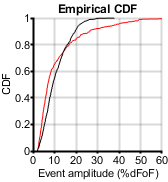

%print(gcf,'-dpdf')
 % CDF
 figure
h1 = cdfplot(tectaTMEventAmp);
hold on
h2 = cdfplot(tmemEventAmp);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Event amplitude (%dFoF)');
ylabel('CDF');
xlim([0 60])
xticks([0 10 20 30 40 50 60])
figQuality(gcf,gca,[1.75 1.9])

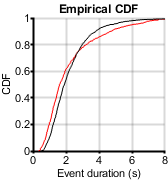

% event width distribution

tmemDur = [tmem1.LICinfo(:,3)',tmem1.RICinfo(:,3)',tmem2.LICinfo(:,3)',tmem2.RICinfo(:,3)',tmem3.LICinfo(:,3)',tmem3.RICinfo(:,3)',tmem4.LICinfo(:,3)',tmem4.RICinfo(:,3)',tmem5.LICinfo(:,3)',tmem5.RICinfo(:,3)',tmem6.LICinfo(:,3)',tmem6.RICinfo(:,3)',tmem7.LICinfo(:,3)',tmem7.RICinfo(:,3)',tmem8.LICinfo(:,3)',tmem8.RICinfo(:,3)']/10;
tectaTMDur = [tectaTM1.LICinfo(:,3)',tectaTM1.RICinfo(:,3)',tectaTM2.LICinfo(:,3)',tectaTM2.RICinfo(:,3)',tectaTM3.LICinfo(:,3)',tectaTM3.RICinfo(:,3)',tectaTM4.LICinfo(:,3)',tectaTM4.RICinfo(:,3)',tectaTM6.LICinfo(:,3)',tectaTM6.RICinfo(:,3)',tectaTM7.LICinfo(:,3)',tectaTM7.RICinfo(:,3)',tectaTM8.LICinfo(:,3)',tectaTM8.RICinfo(:,3)',tectaTM9.LICinfo(:,3)',tectaTM9.RICinfo(:,3)',tectaTM10.LICinfo(:,3)',tectaTM10.RICinfo(:,3)']/10;

figure
h1 = cdfplot(tectaTMDur);
hold on
h2 = cdfplot(tmemDur);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Event duration (s)');
ylabel('CDF');
xlim([0 8])
xticks([0 2 4 6 8])
figQuality(gcf,gca,[1.75 1.9])

[h p2] = kstest2(tmemDur,tectaTMDur);
 p2

p2 = 6.3725e-08

 
[CorrP CorrA h] = fdr_BH([p1,p2],0.05)

CorrP =     0.0020    0.0000


CorrA =     0.0500    0.0250


h = 2×1 logical array
   1
   1


## spatial analysis

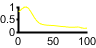

tmem1 = load('spatialAnalysis196_3.mat');
tmem2 = load('spatialAnalysis208_2.mat');
tmem3 = load('spatialAnalysis326_3.mat');
tmem4 = load('spatialAnalysis242_2.mat');
tmem5 = load('spatialAnalysis203_3.mat');
tmem6 = load('spatialAnalysis235_3.mat');
% others have too much rotational movement around edges even with moco

tectaTM1 = load('spatialAnalysis203_1.mat');
tectaTM2 = load('spatialAnalysis208_1.mat');
tectaTM3 = load('spatialAnalysis326_2.mat');
tectaTM4 = load('spatialAnalysis214_1.mat');
tectaTM5 = load('spatialAnalysis235_2.mat');
tectaTM6 = load('spatialAnalysis203_2.mat'); % dim retinal waves
tectaTM7 = load('spatialAnalysis242_1.mat');
tectaTM8 = load('spatialAnalysis280_1.mat');

 % plotting spatial distribution - for 242_2 control
 figure
  plot(tmem4.smRIC(:,2004)./max(tmem4.smRIC(:,2004)),'y')
  ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

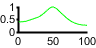

 
figure
  plot(tmem4.smRIC(:,2175)./max(tmem4.smRIC(:,2175)),'g')
   ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

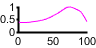

 
 figure
    plot(tmem4.smRIC(:,2707)./max(tmem4.smRIC(:,2707)),'m')
     ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

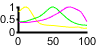

 
  figure  
 tmem4 = load('spatialAnalysis242_2.mat');
 plot(tmem4.smRIC(:,2004)./max(tmem4.smRIC(:,2004)),'y')
 hold on
 % plot(tmem4.smRIC(:,1024)./max(tmem4.smRIC(:,1024)),'g')
 plot(tmem4.smRIC(:,2175)./max(tmem4.smRIC(:,2175)),'g')
  plot(tmem4.smRIC(:,2707)./max(tmem4.smRIC(:,2707)),'m')
 ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

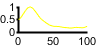

 
% for 326_2 cKO
 
  figure
  plot(tectaTM3.smRIC(:,3821)./max(tectaTM3.smRIC(:,3821)),'y')
  ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

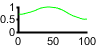

 
figure
  plot(tectaTM3.smRIC(:,2678)./max(tectaTM3.smRIC(:,2678)),'g')
   ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

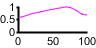

 
 figure
    plot(tectaTM3.smRIC(:,2709)./max(tectaTM3.smRIC(:,2709)),'m')
     ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

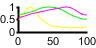

 
  figure  
 plot(tectaTM3.smRIC(:,3821)./max(tectaTM3.smRIC(:,3821)),'y')
 hold on
 plot(tectaTM3.smRIC(:,2678)./max(tectaTM3.smRIC(:,2678)),'g')
  plot(tectaTM3.smRIC(:,2709)./max(tectaTM3.smRIC(:,2709)),'m')
 ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

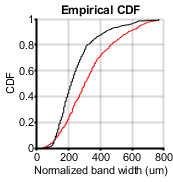

 
perctile = 0.75;
scale = 7.6777; % microns perpixel
% calculate BW of all normalized events 
tmem1BW = getSpatialBW(tmem1,perctile);
tmem2BW = getSpatialBW(tmem2,perctile);
tmem3BW = getSpatialBW(tmem3,perctile);
tmem4BW = getSpatialBW(tmem4,perctile);
tmem5BW = getSpatialBW(tmem5,perctile);
tmem6BW = getSpatialBW(tmem6,perctile);

tmemBW = [tmem1BW,tmem2BW, tmem3BW, tmem4BW, tmem5BW, tmem6BW]*scale;

tectaTM1BW = getSpatialBW(tectaTM1,perctile);
tectaTM2BW = getSpatialBW(tectaTM2,perctile);
tectaTM3BW = getSpatialBW(tectaTM3,perctile);
tectaTM4BW = getSpatialBW(tectaTM4,perctile);
tectaTM5BW = getSpatialBW(tectaTM5,perctile);
tectaTM6BW = getSpatialBW(tectaTM6,perctile);
tectaTM7BW = getSpatialBW(tectaTM7,perctile);
tectaTM8BW = getSpatialBW(tectaTM8,perctile);

tectaTMBW = [tectaTM1BW,tectaTM2BW,tectaTM3BW,tectaTM4BW,tectaTM5BW,tectaTM6BW,tectaTM7BW,tectaTM8BW]*scale;

figure
h1 = cdfplot(tectaTMBW);
hold on
h2 = cdfplot(tmemBW);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Normalized band width (um)');
ylabel('CDF');
xlim([0 800])
xticks([0 200 400 600 800])
figQuality(gcf,gca,[1.8 1.9])

[h p] = kstest2(tectaTMBW,tmemBW);
 p

p = 1.6325e-23

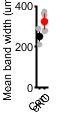

 
 % mean bandwidth by animal
 tmemBWmean = [mean(tmem1BW),mean(tmem2BW),mean(tmem3BW),mean(tmem4BW),mean(tmem5BW),mean(tmem6BW)]*scale;
 tectaTMBWmean = [mean(tectaTM1BW),mean(tectaTM2BW),mean(tectaTM3BW),mean(tectaTM4BW),mean(tectaTM5BW),mean(tectaTM6BW),mean(tectaTM7BW),mean(tectaTM8BW)]*scale;
 
 conditions2 = {'Con','cKO'};
dim = [0.6 1.2];
ylbl1 = 'Mean band width (um)';
[fig1 h p1] = compare2(tmemBWmean,tectaTMBWmean,conditions2,ylbl1,dim);
ylim([0 400])
yticks([0 200 400])

p1

p1 = 0.0020

mean(tmemBWmean)

ans = 249.9742

mean(tectaTMBWmean)

ans = 325.6456

std(tmemBWmean)

ans = 25.4212

std(tectaTMBWmean)

ans = 41.3954